Q1.a)

Code for finding the great circle distance between 2 points given as lat, long

% object containing lat, lon as bristol.lat, bristol.long
bristol = struct('lat', 51.4545, 'lon', -2.5879);
london = struct('lat', 51.5072, 'lon', -0.1276);

bris = [51.4545, -2.5879];
lond = [51.5072, -0.1276];


% define curvature of the earth
wgs84 = wgs84Ellipsoid('kilometer');

% distance() can take either lat, lon seperately or together
d = distance(bristol.lat, bristol.lon, london.lat, london.lon, wgs84)

d = 171.0086

d = distance(bris, lond, wgs84)

d = 171.0086

b)

Converting lat, lon into 12 digit Ordnance Survey grid reference

% define coordinate system, ordnance survey 
crs = projcrs(27700);

% convert lat, lon to eastings/northings
[e, n] = projfwd(crs, bristol.lat, bristol.lon);

% again it can be vectorised with lists of lat and long
latTemp = [bristol.lat, london.lat];
lonTemp = [bristol.lon, london.lon];
projfwd(crs, latTemp, lonTemp)

ans = 1.0e+05 *

    3.5916    5.2993



% truncate to the first 6 digits
e = num2str(e);
e = str2double(e(1:6))

e = 359155


n = num2str(n);
n = str2double(n(1:6))

n = 173053


clearvars('lonTemp','latTemp')


c)

plotting coords over a map of the UK

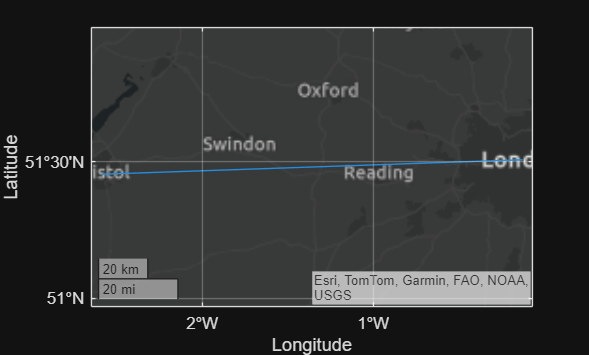

figure
geoplot([bristol.lat, london.lat], [bristol.lon, london.lon])

d)

creating a voroni tesselation of locations and an adjacency matrix of neighbours

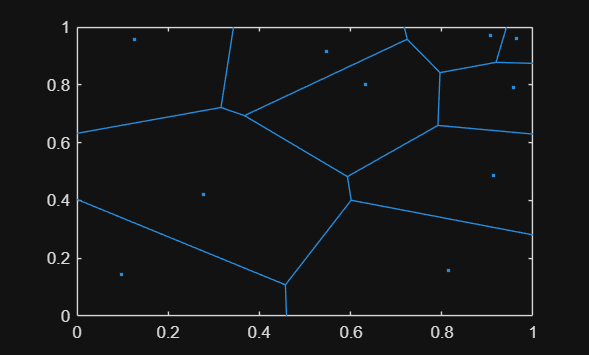

rng default;
figure

% generate n random points
n = 10;
p = rand([n, 2]);

% build visual voronoi diagram
voronoi(p(:, 1), p(:, 2))


% need edge vertex information to build adjacency matrix
[v, c] = voronoin(p);

A = zeros(n);

for i = 1:n
    for j = 1:n
        if length(intersect(c{i}, c{j})) >= 2
            A(i, j) = 1;
            A(j, i) = 1;

        end
    end
end

A

A =      1     0     0     1     0     1     1     0     0     0
     0     1     1     0     1     0     0     1     1     1
     0     1     1     0     0     1     1     1     0     0
     1     0     0     1     1     0     1     0     1     0
     0     1     0     1     1     0     1     1     1     0
     1     0     1     0     0     1     1     0     0     0
     1     0     1     1     1     1     1     1     0     0
     0     1     1     0     1     0     1     1     0     0
     0     1     0     1     1     0     0     0     1     1
     0     1     0     0     0     0     0     0     1     1
